# Push Button Control with 74HC165 Shift Register

This example shows how to use the MATLAB® Support Package for Arduino® Hardware to collect large number of push button states with a 74HC165 8-bit parallel-in-serial-out shift register. This example uses four push buttons.

## Hardware Requirements

- Arduino board

- Four push buttons

- 74HC165 8-bit parallel-in-serial-out shift register

- Four 10K ohm resistors

- Breadboard and wires

## Hardware Setup

Connect push buttons and 74HC165 shift registers to Arduino hardware:

- Connect Vcc pin on 74HC165 to 5V pin on Arduino hardware.

- Connect GND pin on 74HC165 to GND pin on Arduino hardware.

- Connect Q7 pin on 74HC165 to digital pin 11 on Arduino hardware.

- Connect CP pin on 74HC165 to digital pin 8 on Arduino hardware.

- Connect PL pin on 74HC165 to digital pin 9 on Arduino hardware.

- Connect CE pin on 74HC165 to digital pin 10 on Arduino hardware.

- Connect a push button to pin D0, D4, D5 and D7 on 74HC165 with a pull down resistor to GND as shown below.

- Connect pin D1, D2, D3 and D6 on 74HC165 to GND pin on Arduino hardware.

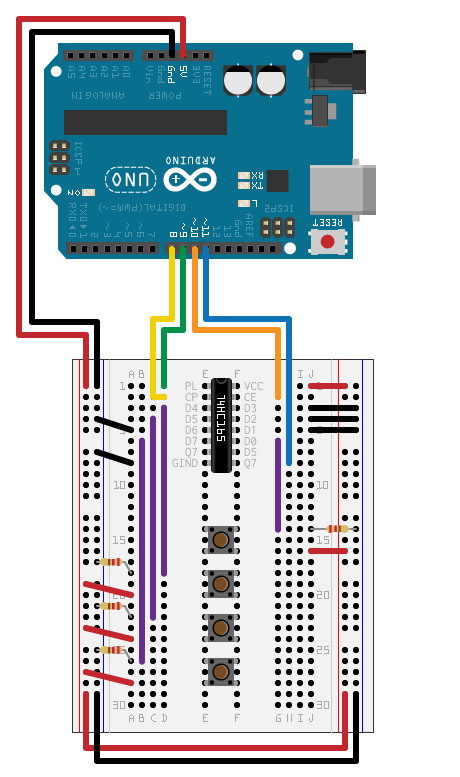

## Create Shift Register Object

Create an arduino object, and include the ShiftRegister library. 

   a = arduino('COM4','Uno','Libraries','ShiftRegister')

Create shift register object, specifying the connected data pin, clock pin, load pin, and clock enable pin. 

   dataPin = 'D11';
   clockPin = 'D8';
   loadPin = 'D9';
   clockEnablePin = 'D10';
   register = shiftRegister(a,'74HC165',dataPin,clockPin,loadPin,clockEnablePin)

## Read Push Button States

Monitor the states of the four push buttons, and print out a message if at least one button is pressed,

    states = read(register, 8);
    pressedButtons = find(states == 1)-1;
    if ~isempty(pressedButtons)
        bitsStr = num2str(pressedButtons, '%d ');
        disp(['Push button(s) connected to bit ', bitsStr, ' is pressed']);
    end

## Clean Up

When the connection is no longer needed, clear the shift register and arduino object.

  clear register a

*Copyright 2016 The MathWorks, Inc.*